# Connect and Sample data from a Hokuyo URG-40LX Laser Scanner

The widely available Hokuyo URG-04LX LIDAR sensors are the robotics world low-cost planar range sensors of choice. Rather than giving the robot a single range measurement over a short range, the Hokuyo LIDAR will allow 240 polar range measurements, within a single plane, over a 10m range.

Before running this code please check what USB comport your Lidar is plugged into and then run the UrgBenriPlusV2.2.0 Hokuyo viewer to make sure the Lidars fully operational and wasn't left in a jammed state.

You can run code sequentially, section by section, but be aware backing up or running sections out of sequential Serial ports are tricky beasts and don't like it if you don't open and close them carefully.

Original code copy right The MathWorks, Inc 2019. This code has been heavily modified 2-4-2022 to support Olin Fun-Robo Lidar Lab by D.Barrett.

disp('program running'); 

program running


% Due to the complexity of talking with the Hokuyo over a Windows 10 serial link, 
% parts of this code are bit wonky and sometimes throws some non-fatal errors when running.
% We will turn off error warnings for now till course staff or students can find and fix this.
warning('off','all');
% Temporarily turn Matlab warnings off
% Lidar is contained in a Matlab serial object, we need to clean up any old lidar 
% objects in the work space to prevent conflicts when creatign a new one.
% Search for and delete old ones. For Fun-Robo, don't worry about what an 
% object is for now, just treat it like a big fancy function.
serialObjs = instrfind;         % Read instrument objects from memory to MATLAB workspace
if ~isempty(serialObjs)         % If there are old objects close them
    fclose(serialObjs);         % close serial port attached to old Lidar
    delete(serialObjs);         % delete old lidar objects
end
% The following code clears up Matlab Workspace of any old work that might 
% conflict with your active code 
clear 
clc
close all

## Specify which serial port (USB) you have the test bench Hokuyo Lidar Plugged into

comPort = '/dev/tty.usbmodem141301'

comPort = '/dev/tty.usbmodem141301'

disp('Com port set')

Com port set


## Connect to Hokuyo Lidar and set its serial communication parameters

s = serial('port') creates a serial port objects associated with the serial port specified by 'port'. 

If 'port' does not exist, or if it is in use, you cannot connect the serial port object to the device. 

codefix? serial object will be removed in a future release. Need to shift to newer serialport object instead. replace serial with serialport(comPort, 'baudrate' 115200) ?

disp ('connecting to lidar and setting Lidar parameters');

connecting to lidar and setting Lidar parameters


disp('expect a short delay while setting......');

expect a short delay while setting......


lidar = serial(comPort, 'baudrate', 115200);    % create a serial port for lidar
set(lidar,'Timeout',2);                         % set communication link timeout
set(lidar,'InputBufferSize',20000);             % set data input buffer size (how many bytes of data can be stored)
set(lidar, 'Terminator','LF/CR');               % set data stream terminator for fprinf and fscanf. 
                                                % A read operation with fget1,fets, or fscanf completes 
                                                % when the terminator value is read.
% write a set of Hokuyo parameters to Lidar to configure it.
fopen(lidar);               % connects the serial port object, the lidar.
pause(0.3);                 % pause to allow command to transmit
fprintf(lidar,'SCIP2.0');   % writes string cmd to lidar
pause(0.3);                 % pause to allow cmd to be sent
fscanf(lidar);               % reads ASCII data from the device connected to lidar
fprintf(lidar,'VV');
pause(0.3);                 % pause to allow data to be read
fscanf(lidar);
fprintf(lidar,'BM');
pause(0.3);
fscanf(lidar);
fprintf(lidar, 'MD0044072500');
pause(0.3);
fscanf(lidar);
clc
disp('Lidar Set')

Lidar Set


## Initialize Arduino

arduinoPort = '/dev/tty.usbmodem141201'

arduinoPort = '/dev/tty.usbmodem141201'

robotArduino = arduino(arduinoPort, 'Mega2560', 'Libraries', 'Servo') ;

panServo=servo(robotArduino,'D33','MinPulseDuration', 10*10^-6, ...
'MaxPulseDuration', 1925*10^-6) ;


## Initialize the Lidar display figure window

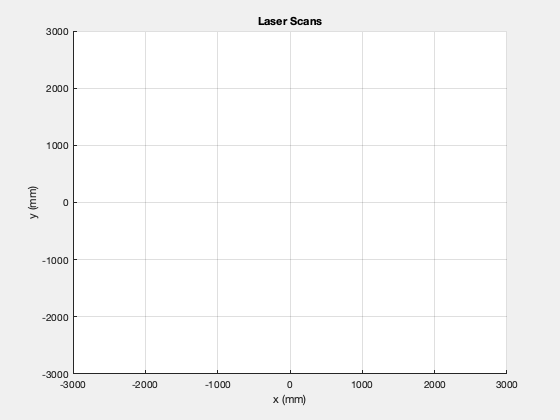


% figure creates a stand-alone figure window. The resulting figure is the
% current figure for all plots until you change it.

LaserPlot1.figure = figure('Name','Hokuyo URG-04LX data','NumberTitle','off', ...
                    'MenuBar','figure','units','normalized','Visible','on');
LaserPlot1.axis1 = axes('Parent',LaserPlot1.figure,'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';
% create a primative line object to use plotting lidar data
% XData and YData are empty vectors waiting to be filled with Lidar data
laserRange = line('Parent', LaserPlot1.axis1, 'XData',[],'YData',[],'LineStyle','none', ...
             'marker','.','color','b','LineWidth',2);
grid on
axis([-3000 3000 -3000 3000])
xlabel('x (mm)')
ylabel('y (mm)')


disp('Laser Scans figure set');

Laser Scans figure set


% close all
angles = (-120:240/682:120-240/682)*pi/180;    % Convert sensor steps to angles for plotting


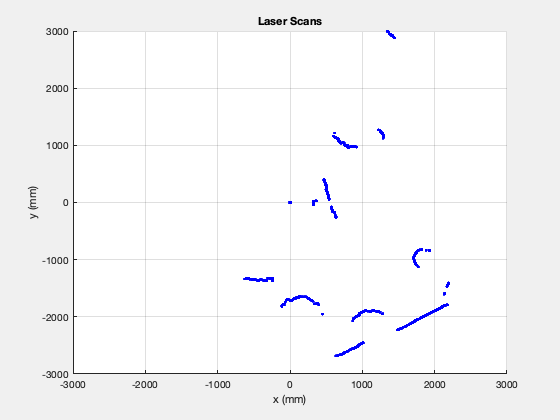

Unable to receive data from the target hardware.
 For MATLAB, reconnect the target hardware, clear the hardware objects and try again.
 For Simulink, reconnect the target hardware and start simulation again.

% pause(3);
beep;
vector_cone = zeros(50, 682);

for i = 0:49

    command = i/100;
    writePosition(panServo, command);
    [A] = FunRoboLidarScan(lidar);               % actual lidar scan range data stored in [A]
    vector_cone(i+1,:) = A;
    pause(0.3);
    laserRange.XData = A.*cos(angles);          % use trig to find x-coord of range
    laserRange.YData = A.*sin(angles);   
    drawnow

end

beep;

## Sample and Visualize Data

read Lidar over USB port, parse data, create a plot of data in a 60 sec continuous loop, use CTRL-c to stop early.

**Note: Please don't pause and leave this section of the code, as it needs to complete and then go through a clean shutdown in next section to avoid jamming the communication link to the Lidar.**

Note: please download the two support Matlab function and then place them in the working folder with this code before proceeding.

[num, whatever] = size(vector_cone);

pan_angles = (-120:240/682:120-240/682)*pi/180;    % Convert sensor steps to angles for plotting
[x,y,z] = get_lidar_plane(vector_cone(1,:),pan_angles);
l = 105;


x_servo = zeros(num,682);
y_servo = zeros(num,682);
z_servo = zeros(num,682);


for (i = 0:num-1)
    commanded = i/100;
    tilt_angle = (2.355  * commanded -.8725);
    rotation = rotational(tilt_angle);
    [x,y,z] = get_lidar_plane(vector_cone(i+1,:),pan_angles);
    mat = [x;y;z];
    for (j = 1:682)
        tmp = rotation*mat(:,j);

        x_servo(i+1,j) = tmp(1);
        y_servo(i+1,j) = tmp(2) + l*cos(tilt_angle);
        z_servo(i+1,j) = tmp(3) + l*sin(tilt_angle);

    end
end


figure;
plot3(x_servo,y_servo, -z_servo,'o','color','b')
set(gcf,'visible','on');
xlabel('x(mm)')
ylabel('y(mm)')
zlabel('z(mm)')
ylim([0,inf])


## Disconnect Lidar and cleanly close USB serial link

Please always run this section before exiting this mix file. Failing to do so will leave USB link open and prevent you from attaching to Lidar for any follow on worl. TO clear the serial jam this causes, you will need to shut down matlab and unplug Lidar and reboot your laptop.

***PLEASE  ALWAYS RUN THIS LIDAR DISCONNECT SECTION***

fprintf(idare,'QT'); % writes the string quit to the lidar
fclose(lidar);       % disconnect lidar obj from serial port object
clear lidar;         % clear lidar obj from memory
warning('on');       % turn Matlab warnings back on
disp('program ended');

function [x,y,z] = get_lidar_plane(d,pan_angles)
    y = d.*cos(pan_angles);
    x = d.*sin(pan_angles);
%     z = 1150*ones(1,682);
    z = zeros(1,682);
end

function [rotation] = rotational(theta)
%     rotation = [1 0 0 ; 0 cos(theta) -sin(theta); 0 sin(theta) cos(theta)];
    rotation = rotx(rad2deg(theta));
end